# Understand what is happening in the build expanded model

## Load a toy model

loading a small toy model instaed of the big recon, in order to understand what is happening when the model is expanded in order to reflect a multicell population within a common space (compartment [u]).

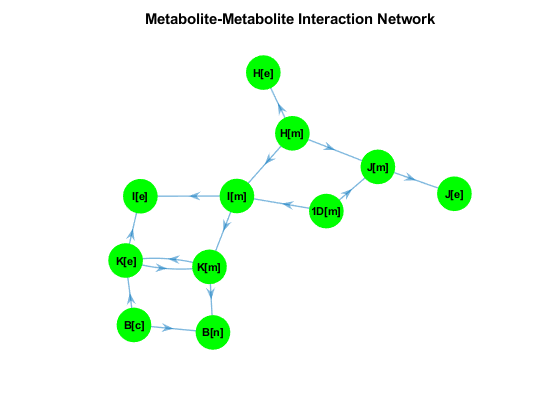

clc
clear
fields_to_keep={'S','rxns', 'mets', 'metFormulas','genes', 'rules', 'grRules', 'b', 'rxnGeneMat','c', 'lb', 'ub', 'rev', 'subSystems','metFormulas'};
addpath(genpath("\\atlas.uni.lux\fstc_sysbio\0- UserFolders\Leonie.THOMAS\projects\20241230_toy_model_multi_model_construction"))
addpath(genpath("C:\Users\leonie.thomas\scFASTCORMICS"))
number_of_cluster = 3;
% script to load the small toy model
small_model = 1;
load_toy_model

expand_model_understood


%% PUTTING RXNS ARRAY TOGETHER AND INTO THE RIGHT SLOT 


% after looping over the slots separatly and creating a array for all the
% different rxns types: internal, transport, intercluster_transport and
% exchange - this section then puts them all togehter and assigns them into
% the correct slot in the model object
for ii=1:numel(fields)
    if size( model.(fields{ii}),1)==size( model.rxns,1) && size( model.(fields{ii}),1)~=size( model.mets,1)
        if iscell(expanded_input_model.(fields{ii}))
            
            rul=[internal_rxns_array(:,ii+1);intercluster_trans_array(:,ii+1);cell(numel(trans),1);cell(numel(Ex),1)];
            rul(cellfun('isempty',rul))=cellstr('');
            expanded_input_model.(fields{ii})=rul;
            
        else
            if strcmp(fields{ii}, 'lb')
                
                %% lower bounds set -1000 by defaut for trans and Ex
                expanded_input_model.(fields{ii})=[internal_rxns_array_n(:,ii+1);intercluster_trans_array_n(:,ii+1);ones(numel(trans),1)*-1000; ones(numel(Ex),1)*-1000];
            else
                % c & rev  - why median ? 
                expanded_input_model.(fields{ii})=[internal_rxns_array_n(:,ii+1);intercluster_trans_array_n(:,ii+1);ones(numel(trans),1)*median(internal_rxns_array_n(:,ii+1)); ones(numel(Ex),1)*median(internal_rxns_array_n(:,ii+1))];
            end
        end
    else
        if iscell(expanded_input_model.(fields{ii}))
            [~,index]=ismember(exmets,model.mets);
            temp2=cell(numel(exmets),1);
            temp=model.(fields{ii});
            temp2(index>0)=temp(index(index>0));
            expanded_input_model.(fields{ii})=[expanded_input_model.(fields{ii});temp2;temp2];
        else
            % b slot - why the mean ? 
            expanded_input_model.(fields{ii})=[expanded_input_model.(fields{ii});ones(numel(umets),1)*mean(expanded_input_model.(fields{ii}));ones(numel(umets),1)*mean(expanded_input_model.(fields{ii}))];
        end
    end
end


 table(expanded_input_model.S)



%% FINALIZING THE RXNS SLOT IN THE EXPANDED MODEL

% creating a Trans and Ex rxn for every ex met in u compartment
trans=strcat('Trans_',sort(exmets));
Ex=strcat('Ex_',exmets);
dico_EX=cell(numel(Ex),2);
dico_EX(:,1)=Ex;
% find the rxns for the ex mets 
for i=1:numel(exmets)
    r=find(model.S(ismember(model.mets,exmets(i)),:));
    r=intersect(model.rxns(r),exRxns);
    dico_EX(i,2)=r;
end
% add all the rxns to the rxns slot of the model
expanded_input_model.rxns=[internal_rxns_array(:,1);intercluster_trans_array(:,1);trans;Ex];

%% PUTTING RXNS ARRAY TOGETHER AND INTO THE RIGHT SLOT + Adding the missing information about Exchange and Transport rxns


for ii=1:numel(fields)
    if size( model.(fields{ii}),1)==size( model.rxns,1) && size( model.(fields{ii}),1)~=size( model.mets,1)
        if iscell(expanded_input_model.(fields{ii}))
            
            rul=[internal_rxns_array(:,ii+1);intercluster_trans_array(:,ii+1);cell(numel(trans),1);cell(numel(Ex),1)];
            rul(cellfun('isempty',rul))=cellstr('');
            expanded_input_model.(fields{ii})=rul;
            
        else
            if strcmp(fields{ii}, 'lb')
                
                %% lower bounds set -1000 by defaut for trans and Ex
                expanded_input_model.(fields{ii})=[internal_rxns_array_n(:,ii+1);intercluster_trans_array_n(:,ii+1);ones(numel(trans),1)*-1000; ones(numel(Ex),1)*-1000];
            else
                % c & rev  - why median ? 
                expanded_input_model.(fields{ii})=[internal_rxns_array_n(:,ii+1);intercluster_trans_array_n(:,ii+1);ones(numel(trans),1)*median(internal_rxns_array_n(:,ii+1)); ones(numel(Ex),1)*median(internal_rxns_array_n(:,ii+1))];
            end
        end
    else
        if iscell(expanded_input_model.(fields{ii}))
            [~,index]=ismember(exmets,model.mets);
            temp2=cell(numel(exmets),1);
            temp=model.(fields{ii});
            temp2(index>0)=temp(index(index>0));
            expanded_input_model.(fields{ii})=[expanded_input_model.(fields{ii});temp2;temp2];
        else
            % b slot - why the mean ? 
            expanded_input_model.(fields{ii})=[expanded_input_model.(fields{ii});ones(numel(umets),1)*mean(expanded_input_model.(fields{ii}));ones(numel(umets),1)*mean(expanded_input_model.(fields{ii}))];
        end
    end
end

%% correct reversibility - 
lb=zeros(numel(exmets),1);
ub=zeros(numel(exmets),1);
grRules=cell(numel(exmets),1);
R_ex=cell(numel(exmets),1);
% since the ex rxns are still defined as 1 in the s matrix the sign needs
% to be flipped - toy model convention ? Recon convention ???
for i=1:numel(exmets)
    [~,r]=find(model.S(ismember(model.mets,exmets(i)),:));
    r=intersect(model.rxns(r),exRxns);
    R_ex(i,1)=r;
    
    sign=model.S(ismember(model.mets,exmets(i)),ismember(model.rxns,r));
    if full(sign) >0
        % then flip
        model.S(ismember(model.mets,exmets(i)),ismember(model.rxns,r))=-sign;
        tmp=model.ub(ismember(model.rxns,r));
        model.ub(ismember(model.rxns,r))=-model.lb(ismember(model.rxns,r));
        model.lb(ismember(model.rxns,r))=-tmp;
    end
end
% this part I do not get... - 
% so we create lb and ub with all zeros, then we manibulate this 
% we get the indices of the R_ex in the model.rxns 
[~,index]=ismember(R_ex,model.rxns);
% then we filter out all the R_ex which are not in the model.rxns by
% excluding the zero entrie in the indices vector
lb(index>0)=model.lb(index(index>0));
ub(index>0)=model.ub(index(index>0));
% transfer the lb & ub from the consensus model to the expanded model, the
% indices of the ex rxns change between those two models, therefore this
% transfer is needed

Table_bound=table(R_ex,lb, ub, exmets,strcat('Ex_',exmets));
[~,index]=ismember(expanded_input_model.rxns,table2array(Table_bound(:,5)));
expanded_input_model.lb(index>0)=Table_bound.lb(index(index>0));
expanded_input_model.ub(index>0)=Table_bound.ub(index(index>0));



%%
% now the reversibility slot is fixed, for all the rxns the lb were set,
% so for the rxns which have a negative lb we can assume that they are
% reversible 
expanded_input_model.rev= sparse(numel(expanded_input_model.rxns),1);
expanded_input_model.rev(expanded_input_model.lb<0)=1;


%%
% building the RxnGene matrix from grRules slot
expanded_input_model = buildRxnGeneMat(expanded_input_model);
% creating the .rule slot from grRules
expanded_input_model = creategrRulesField(expanded_input_model);
% fixing Irr rxns ? what does that mean? 
expanded_input_model=fixIrr_rFASTCORMICS(expanded_input_model);

% % this is the fixIrr function code: 
% model.rev = zeros(numel(model.rxns),1);
% % the  
% model.rev(model.lb <0 & model.ub> 0) = 1;
% Irr=(model.lb >=0 & model.ub>0| model.ub<=0 & model.lb<0);
% model.rev(Irr) = 0;
% FakeIrr= model.ub <=0 & model.lb<0;
% model.S(:, FakeIrr) = -model.S(:,FakeIrr);
% model.ub(FakeIrr) = -model.lb(FakeIrr);
% model.lb(FakeIrr) = zeros(sum(FakeIrr),1);

%% 
% correct rules for exchanges
% question: the exchange rxns are empty bevore and after -> 
% first of all, why do this code in the frist place and why should exhange
% reactions have a gprule ? 

[~,index]=ismember(R_ex,model.rxns);
grRules(index>0)=model.grRules(index(index>0));
% getting the rules for the exchange rxns from the consistent generic model
% then adding to the table for the exchange reactions 
Table_bound=[Table_bound,table(grRules)];
rules_keep=cell(size(Table_bound,1),1);
for counter2=1:size(Table_bound,1)
    if ~cellfun('isempty',table2array(Table_bound(counter2,6)))
        
        
        for counter=1:number_of_cluster
            if counter==1
                rules=strcat(table2array(Table_bound(counter2,6)),'_', num2str(counter));
            else
                tmp= strcat(table2array(Table_bound(counter2,6)),'_',num2str(counter));
                rules=strcat(string(rules), ' or ','$ ', string(tmp));
            end
        end
        rules=strrep(rules,'$',' ');
        rules_keep(counter2,1)=cellstr(rules);
    end
    [~,index]=ismember(expanded_input_model.rxns,table2array(Table_bound(:,5)));
    

    expanded_input_model.grRules(index>0)=rules_keep(index(index>0),1);
end
    expanded_input_model.grRules(cellfun('isempty',expanded_input_model.grRules))=cellstr('');
for i=1:numel(expanded_input_model.grRules)
expanded_input_model.grRules(i)=strrep(expanded_input_model.grRules(i),'or',' or ');
     expanded_input_model.grRules(i)=strrep(expanded_input_model.grRules(i),'and',' and ');
end

% update the rules field after altering the grRules slot
expanded_input_model = generateRules(expanded_input_model);




expanded_input_model

expanded_input_model = buildRxnGeneMat(expanded_input_model);

alternative code, up until now it only pasts together the S matrix....a lot more is needed to replicate the script!!

%%% new code from me - to produce the matrices
% int = expand_matrix(eye(number_of_cluster),internal_S_matrix_for_1_cluster);
% int_trans_Smat = expand_matrix(eye(number_of_cluster),intercluster_trans_Smat_4_1_cluster);
% int_trans_Smat2 = expand_matrix([1,1],intercluster_trans_Smat_4_1_cluster2);
% 
% layout_matrix_rxns = "_" + [1:number_of_cluster]; 
% layout_matrix_rxns = [layout_matrix_rxns',repmat("",number_of_cluster,numel(fields))];
% int_rxns_array = expand_matrix(layout_matrix_rxns,internal_rxns);
% int_trans_array = expand_matrix(layout_matrix_rxns,intercluster_transport);
% met = expand_matrix("_" + [1:number_of_cluster]',internal_mets)';
% expanded_genes = expand_matrix("_" + [1:number_of_cluster]',model.genes); 


varname = regexp(exmets, '\[(.*?)\]', 'match', 'once');
expanded_input_model.mets=[mets';sort(strrep(exmets,varname,'[u]'));sort(strrep(exmets,varname,'[e]'))];
umets=strrep(exmets,varname,'[u]');
S=[internal_S_matrix,intercluster_trans_Smat];

S2=[sparse(size(umets,1),size(internal_S_matrix,2)),intercluster_trans_Smat2];
S=[S;S2];
S7=sparse(size(intercluster_trans_Smat,1), numel(exRxns));
S8=[S7;eye(size(intercluster_trans_Smat2,1))*-1];
S2=[S;sparse(size(intercluster_trans_Smat2,1),size(S,2))];
S=[S2, [S8;eye(size(intercluster_trans_Smat2,1))]];

S7=sparse(size(S,1), numel(exRxns));
S7(end+1-size(eye(size(intercluster_trans_Smat2,1)),1):end,:)=eye(size(intercluster_trans_Smat2,1));
S=[S, S7];


expanded_input_model.S=S;
trans=strcat('Trans_',sort(exmets));
Ex=strcat('Ex_',exmets);
dico_EX=cell(numel(Ex),2);
dico_EX(:,1)=Ex;
for i=1:numel(exmets)
    r=find(model.S(ismember(model.mets,exmets(i)),:));
    r=intersect(model.rxns(r),exRxns);
    dico_EX(i,2)=r;
end
expanded_input_model.rxns=[internal_rxns_array(:,1);intercluster_trans_array(:,1);trans;Ex];



for i=1:number_of_cluster
    % genes are copied per cluster with a postfix indicating which cluster
    % they belong to 
    expanded_input_model.genes=[expanded_input_model.genes;strcat(model.genes,'_', num2str(i))];
    
    if i>1
        ind=ind2+1;
        ind3=ind4+1;
        ind5=ind6+1;
        ind7=ind8+1;
    end
    ind2=ind+size(internal_S_matrix_for_1_cluster,1)-1;
    ind4= ind3+ size(internal_S_matrix_for_1_cluster,2)-1;
    ind6=ind5+size(intercluster_trans_Smat_4_1_cluster,1)-1;
    ind8=ind7+size(intercluster_trans_Smat_4_1_cluster,2)-1;    
    ind10=ind9+size(intercluster_trans_Smat_4_1_cluster2,1)-1;
    internal_S_matrix(ind: ind2,ind3:ind4)=internal_S_matrix_for_1_cluster;
    intercluster_trans_Smat(ind5:ind6,ind7:ind8)=intercluster_trans_Smat_4_1_cluster;
    intercluster_trans_Smat2(ind9:ind10,ind7:ind8)=intercluster_trans_Smat_4_1_cluster2;
    internal_rxns_array(ind3:ind4,1)=strcat(internal_rxns,'_', num2str(i));
    mets(ind: ind2)=strcat(internal_mets,'_', num2str(i));
    intercluster_trans_array(ind7:ind8,1)=(strcat(intercluster_transport,'_', num2str(i)));
   % do first metabolites
    for ii=1:numel(fields)
        disp("hello")
        %  here we check if the slot of the model object characterizes the
        %  rxns or the metabolites 
        if size( model.(fields{ii}),1)==size( model.mets,1)&& size( model.(fields{ii}),2)~=size( model.rxns,1)
            % if the rows are equal to the met dimension, then we add the
            % information about the corresponding slot of the
            % internal_mets
            temp=model.(fields{ii});
           
            expanded_input_model.(fields{ii})= [expanded_input_model.(fields{ii});temp(internal_mets_index)];
        elseif size( model.(fields{ii}),1)==size( model.rxns,1) && size( model.(fields{ii}),1)~=size( model.mets,1)
            % put this into a function!
            temp=model.(fields{ii});
            if strcmp(fields{ii},'rules') && i>1
                disp("going into the rules!!")
                %Update the indices of the genes in the rules. The number of total genes is added to the indices for
                %each cluster (i.e 22 + numel(model.genes) * number of
                %clusters. This is done in two steps, the expression is
                %changed. Plus (+) appear in the expressions then it is
                %evaluated to remove the (+)
                
                temp=strrep(temp, 'x(', strcat( 'x(' ,num2str(numel(model.genes)*(i-1)),'+'));
                for counter1=1:numel(temp) 
                    temp2=temp{counter1};
                    plus_pos=strfind(temp2,'+');
                    if ~isempty(plus_pos)
                        bracket1_pos=strfind(temp2,'(');
                        bracket2_pos=strfind(temp2,')');
                        if numel(plus_pos)==1 && numel(bracket2_pos)==1 && numel(bracket1_pos)==1
                            
                            temp3=temp2(bracket1_pos+1: bracket2_pos-1);
                            temp4=eval(temp3);
                            temp{counter1}=strrep(temp2,temp3, num2str(temp4));
                        else
                            while ~isempty(plus_pos)
                                
                                u22= plus_pos(1)-bracket1_pos;
                                u22=bracket1_pos(u22== min(u22(u22>0)));
                                u33= bracket2_pos-plus_pos(1);
                                u33=bracket2_pos(u33== min(u33(u33>0)));
                                temp3=temp2(u22+1: u33-1);
                                temp4=eval(temp3);
                                temp3a=strcat('(',temp3,')');
                                temp4a=strcat('(',num2str(temp4),')');
                                temp2=strrep(temp2,temp3a,temp4a);
                                plus_pos=strfind(temp2,'+');
                                bracket1_pos=strfind(temp2,'(');
                                bracket2_pos=strfind(temp2,')');
                            end
                            temp{counter1}=temp2;
                        end
                    end
                end
            else
            end
            if iscell(temp)
                internal_rxns_array(ind3:ind4,ii+1)=temp(internal_rxns_index);
                intercluster_trans_array(ind7:ind8,ii+1)=temp(intercluster_transportID);
            else
                internal_rxns_array_n(ind3:ind4,ii+1)=temp(internal_rxns_index);
                if strcmp(fields{ii}, 'lb')
                    
                    intercluster_trans_array_n(ind7:ind8,ii+1)=temp(intercluster_transportID);
                else
                    intercluster_trans_array_n(ind7:ind8,ii+1)=temp(intercluster_transportID);
                end
                
            end
            
            expanded_input_model.(fields{ii})= [expanded_input_model.(fields{ii});temp(internal_rxns_index)];
            
        end
    end
    
end

varname = regexp(exmets, '\[(.*?)\]', 'match', 'once');
expanded_input_model.mets=[mets';sort(strrep(exmets,varname,'[u]'));sort(strrep(exmets,varname,'[e]'))];
umets=strrep(exmets,varname,'[u]');
S=[internal_S_matrix,intercluster_trans_Smat];
S2=[sparse(size(umets,1),size(internal_S_matrix,2)),intercluster_trans_Smat2];
S=[S;S2];



S7=sparse(size(intercluster_trans_Smat,1), numel(exRxns));
S8=[S7;eye(size(intercluster_trans_Smat2,1))*-1];
S2=[S;sparse(size(intercluster_trans_Smat2,1),size(S,2))];
S=[S2, [S8;eye(size(intercluster_trans_Smat2,1))]];



S7=sparse(size(S,1), numel(exRxns));
S7(end+1-size(eye(size(intercluster_trans_Smat2,1)),1):end,:)=eye(size(intercluster_trans_Smat2,1));
S=[S, S7];
size(S7)

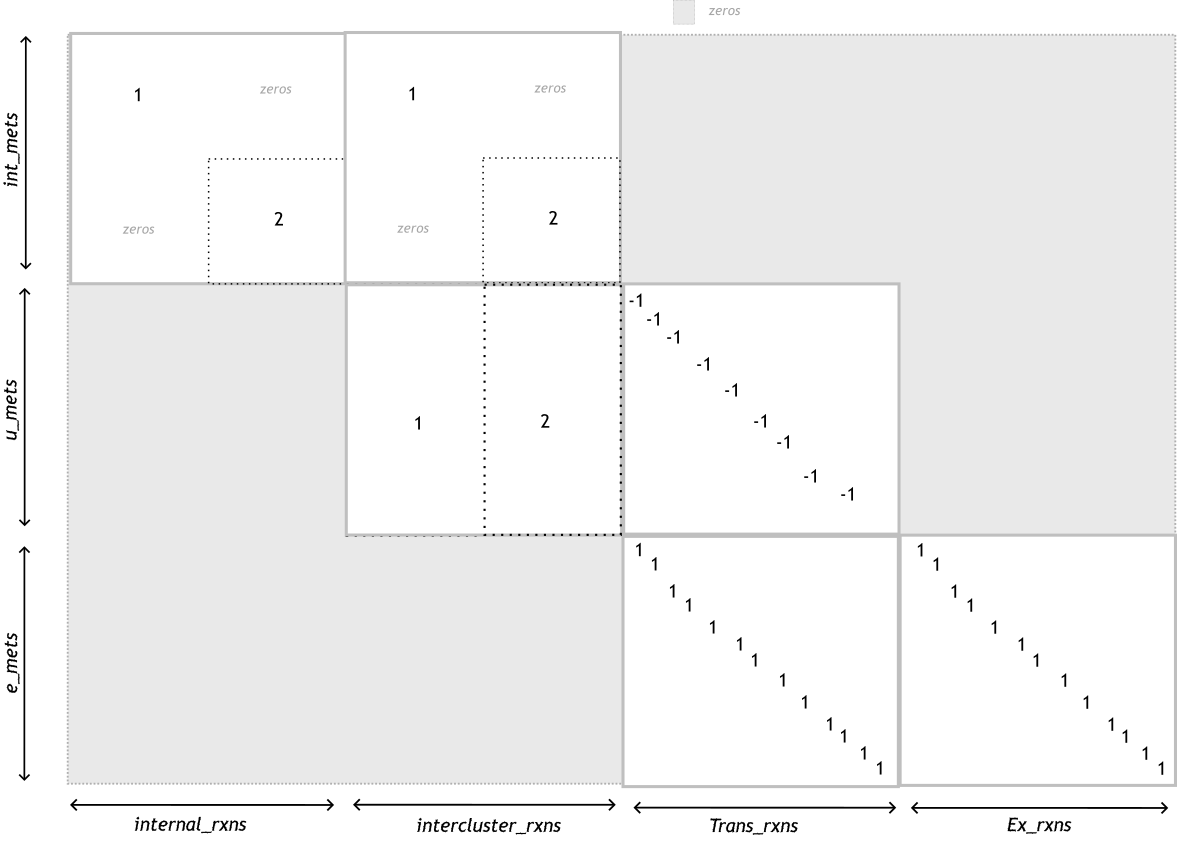


expanded_input_model.S=S;
trans=strcat('Trans_',sort(exmets));
Ex=strcat('Ex_',exmets);
dico_EX=cell(numel(Ex),2);
dico_EX(:,1)=Ex;
for i=1:numel(exmets)
    r=find(model.S(ismember(model.mets,exmets(i)),:));
    r=intersect(model.rxns(r),exRxns);
    dico_EX(i,2)=r;
end
expanded_input_model.rxns=[internal_rxns_array(:,1);intercluster_trans_array(:,1);trans;Ex];

graphObj=createMetIntrcNetwork(expanded_input_model,expanded_inpaut_model.mets);
expanded_input_model.rxns

two_rasters_model = expanded_input_model;
two_rasters_model.S = [expanded_input_model.S,zeros(size(expanded_input_model.S,1),size(expanded_input_model.S,2));
                       zeros(size(expanded_input_model.S,1),size(expanded_input_model.S,2)),expanded_input_model.S];
two_rasters_model.rxns = cellstr([expanded_input_model.rxns + "_u1"; expanded_input_model.rxns + "_u2" ;umets + "_c"]);
two_rasters_model.mets = cellstr([expanded_input_model.mets + "_u1"; expanded_input_model.mets + "_u2" ;umets + "_c"]);

two_rasters_model.S = [two_rasters_model.S,zeros(size(two_rasters_model.S,1), size(umets,1));
                            zeros(size(umets,1),size(two_rasters_model.S,2)),eye(size(umets,1))]


size(two_rasters_model.S)

two_rasters_model.b = [];
two_rasters_model.c = [];
two_rasters_model.genes = [];
two_rasters_model.grRules = [];
two_rasters_model.lb = [];
two_rasters_model.rev = [];
two_rasters_model.rules = [];
two_rasters_model.rxnGeneMat = [];
two_rasters_model.ub = []

graphObj=createMetIntrcNetwork(two_rasters_model,two_rasters_model.mets);
%__add transfers between the compartments_ 

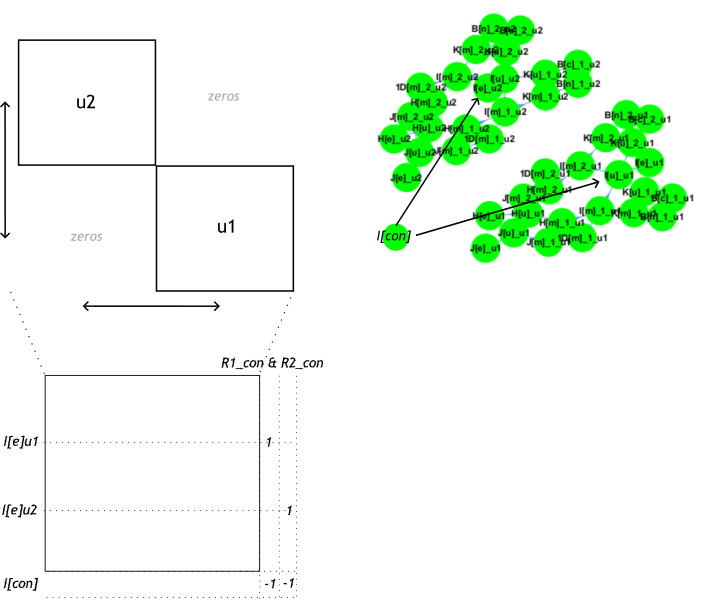

multiple_ele_matrices = 1;
layout_matrix = [1,3;...
                 4,2];
identity_matrices = {[2,4;...
                     8,12],...
                     [1,4;...
                      20,30],...
                     [0,0;
                      0,0],...
                     [1,1;...
                      1,0]};
ele_matrix = [1,0; 4,8];

expand_matrix(layout_matrix, identity_matrices, multiple_ele_matrices)

layout_matrix = [1,2;
                 2,1]

expanded_input_model.S = S;
two_rasters_model.S = [expanded_input_model.S,zeros(size(expanded_input_model.S,1),size(expanded_input_model.S,2));
                       zeros(size(expanded_input_model.S,1),size(expanded_input_model.S,2)),expanded_input_model.S];
two_rasters_model.rxns = cellstr([expanded_input_model.rxns + "_u1"; expanded_input_model.rxns + "_u2"]);
two_rasters_model.mets = cellstr([expanded_input_model.mets + "_u1"; expanded_input_model.mets + "_u2" ]);


function[expanded_matrix] = expand_matrix(layout_matrix, ele_matrix,multiple_ele_matrices)
    %
    % this function does expand a matrix according to another matrix 
    % meaning that the ele matrix will be multiplied by the corresponding
    % element in the layout matrix and then then the matrices are pasted
    % together 
    % say you have:  0 1
    %               -2 0 -> as a layout matrix 
    % then the matrix: 2 2
    %                  3 3 -> as a ele_matrix 
    % will result in: 
    %                  0  0  2  2
    %                  0  0  3  3
    %                 -4 -4  0  0 
    %                 -6 -6  0  0 -> as the expanded matrix!
    %
    % this can also be done in case you want to add a postfix to an matrix:
    %
    % say you have:  "_1" ""
    %                "_2" "" -> as a layout matrix 
    %
    % then the matrix: "rx1" 
    %                  "rx2" -> as a ele_matrix 
    % will result in: 
    %                  rx1_1  ""  ""  ""
    %                  rx2_1  ""  ""  ""
    %                  rx1_2  ""  ""  "" 
    %                  rx2_2  ""  ""  "" -> as the expanded matrix!
    % 
    % parameters: 
    % layout_matrix = eye(number_of_cluster);
    % ele_matrix = internal_S_matrix_for_1_cluster;
    % 
    
    % definition of ifelse function
ternary = @(varargin) varargin{end - varargin{1}};
wanted_dimensions = [size(layout_matrix,1)*size(ele_matrix,1),size(layout_matrix,2)*size(ele_matrix,2)];
if multiple_ele_matrices
    
    a = arrayfun(@(x) ele_matrix{x}', layout_matrix, 'UniformOutput',false);
    if size(layout_matrix,1) == 1
        expanded_matrix = [a{:}];
    end
    
    b= arrayfun(@(x)[a{:,x}]',1:size(layout_matrix,2), 'UniformOutput', false);
    expanded_matrix = [b{:}];
else
    if class(ele_matrix) == "double"
            disp("You have given a numeric elementary matrix!")
            a = arrayfun(@(x) (x.*ele_matrix)', layout_matrix, 'UniformOutput',false);
            if size(layout_matrix,1) == 1
                expanded_matrix = [a{:}];
            elseif size(layout_matrix,1) == 2
                
                b= arrayfun(@(x)[a{:,x}]',1:size(layout_matrix,2), 'UniformOutput', false);
                expanded_matrix = [b{:}];
                
                %b = arrayfun(@(x) reshape([a{:,x}],size(ele_matrix,1),size(ele_matrix,2)*size(layout_matrix,2))', ...
                % 1:size(layout_matrix,2), 'UniformOutput', false);
                %expanded_matrix = [b{:}]';
                %b = arrayfun(@(x) [a{x,:}]', ...
                %             1:size(layout_matrix,2), 'UniformOutput', false);
                %expanded_matrix = reshape([b{:}],size(ele_matrix,1)* size(layout_matrix,1),size(ele_matrix,2)*size(layout_matrix,2));
           
            else
                error('layout matrix is not in the right format! should be a 1xn or 2xn matrix!')
            end
    elseif class(ele_matrix) == "cell" & class(layout_matrix) == "string"
        disp("You have given a character elementary matrix!")
        a = arrayfun(@(x) ternary(x == "",repmat("",size(ele_matrix)),ele_matrix + x), layout_matrix, 'UniformOutput',false);
        expanded_matrix = reshape([a{:}],wanted_dimensions);
        expanded_matrix = arrayfun(@(x) x{:}, expanded_matrix, 'UniformOutput',false);
    else
        error('The layout or/and the elementary matrix do not have the right class! Please check that both of these are in the correct format!! Either only strings or only numeric!!')
    end
    
    if sum(size(expanded_matrix) == wanted_dimensions) ~= 2
        error('The expaned matrix was not expanded into the wanted dimensions, please check why! ')
    end
    
    end
end